# Compare day1 and day2 behavior

% read data
day1_file = 'D:\Ruonan\Projects in the lab\VA_RA_PTB\Analysis Ruonan\Fitpar files\Behavior data fitpar_020519\param_nonparam_day1_020519.txt';
day2_file = 'D:\Ruonan\Projects in the lab\VA_RA_PTB\Analysis Ruonan\Fitpar files\Behavior data fitpar_020519\param_nonparam_day2_020519.txt';
day1 = readtable(day1_file);
day2  =readtable(day2_file);

% calculate model free attitude
day1.G_risk = mean([day1.G_risk25, day1.G_risk50, day1.G_risk75], 2);
day1.G_amb = mean([day1.G_amb24, day1.G_amb50, day1.G_amb74], 2);
day1.G_amb_risk50 = day1.G_amb - day1.G_risk50;
day1.L_risk = mean([day1.L_risk25, day1.L_risk50, day1.L_risk75], 2);
day1.L_amb = mean([day1.L_amb24, day1.L_amb50, day1.L_amb74], 2);
day1.L_amb_risk50 = day1.L_amb - day1.L_risk50;

day2.G_risk = mean([day2.G_risk25, day2.G_risk50, day2.G_risk75], 2);
day2.G_amb = mean([day2.G_amb24, day2.G_amb50, day2.G_amb74], 2);
day2.G_amb_risk50 = day2.G_amb - day2.G_risk50;
day2.L_risk = mean([day2.L_risk25, day2.L_risk50, day2.L_risk75], 2);
day2.L_amb = mean([day2.L_amb24, day2.L_amb50, day2.L_amb74], 2);
day2.L_amb_risk50 = day2.L_amb - day2.L_risk50;

#### Plot day1-day2 correlation

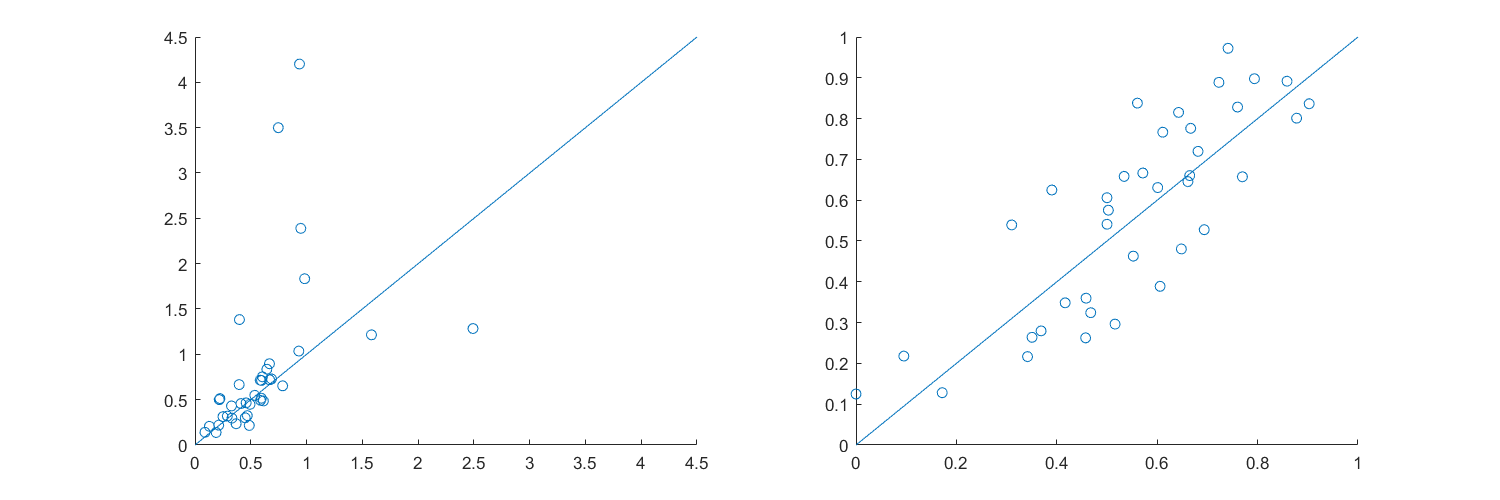

% risk attitude, constrained, gain
figure('Position', [0,0,1200,400])
subplot(1,2,1)
scatter(day1.alpha_2, day2.alpha_2)
x = linspace(0,4.5);
y = x;
line(x,y)

subplot(1,2,2)
scatter(day1.G_risk, day2.G_risk)
x = linspace(0,1);
y = x;
line(x,y)

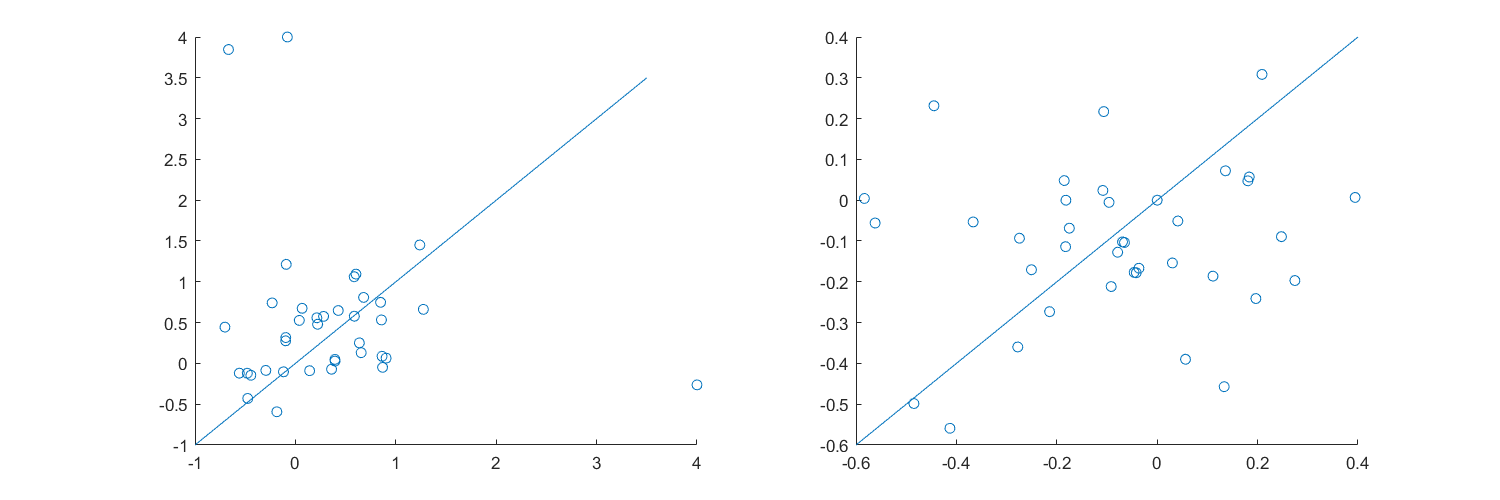

% ambig attitude, constrained, gain
figure('Position', [0,0,1200,400])
subplot(1,2,1)
scatter(day1.beta_2, day2.beta_2)
x = linspace(-1,3.5);
y = x;
line(x,y)

subplot(1,2,2)
scatter(day1.G_amb_risk50, day2.G_amb_risk50)
x = linspace(-0.6, 0.4);
y = x;
line(x,y)

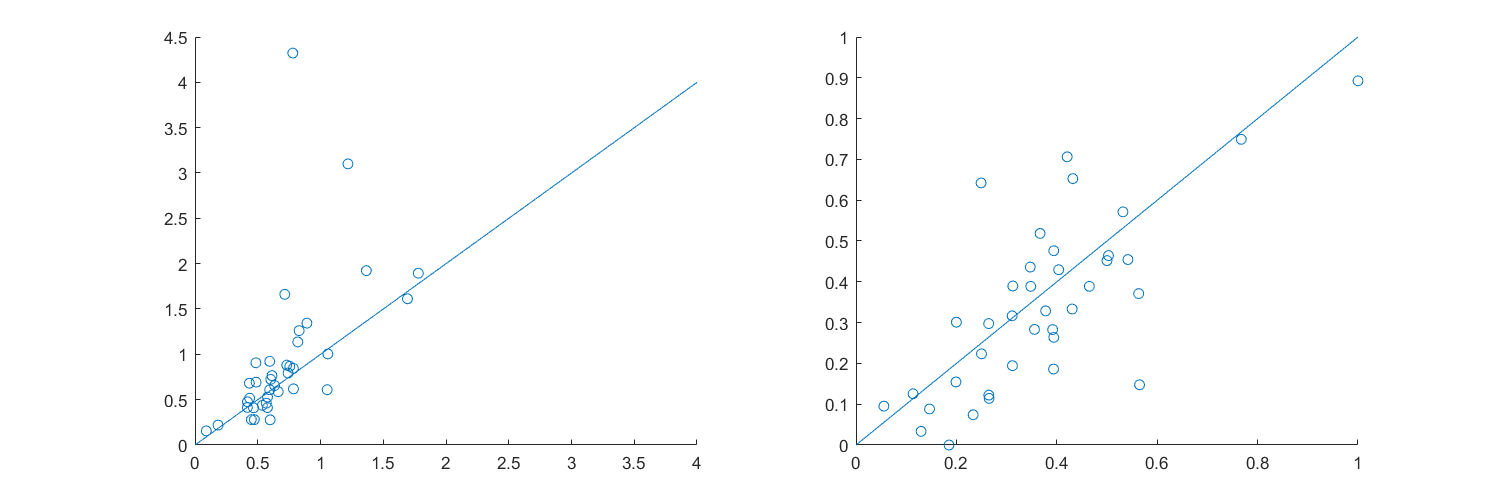

% risk attitude, constrained, loss
figure('Position', [0,0,1200,400])

subplot(1,2,1)
scatter(day1.alpha_3, day2.alpha_3)
x = linspace(0,4);
y = x;
line(x,y)

subplot(1,2,2)
scatter(day1.L_risk, day2.L_risk)
line(linspace(0,1), linspace(0,1))

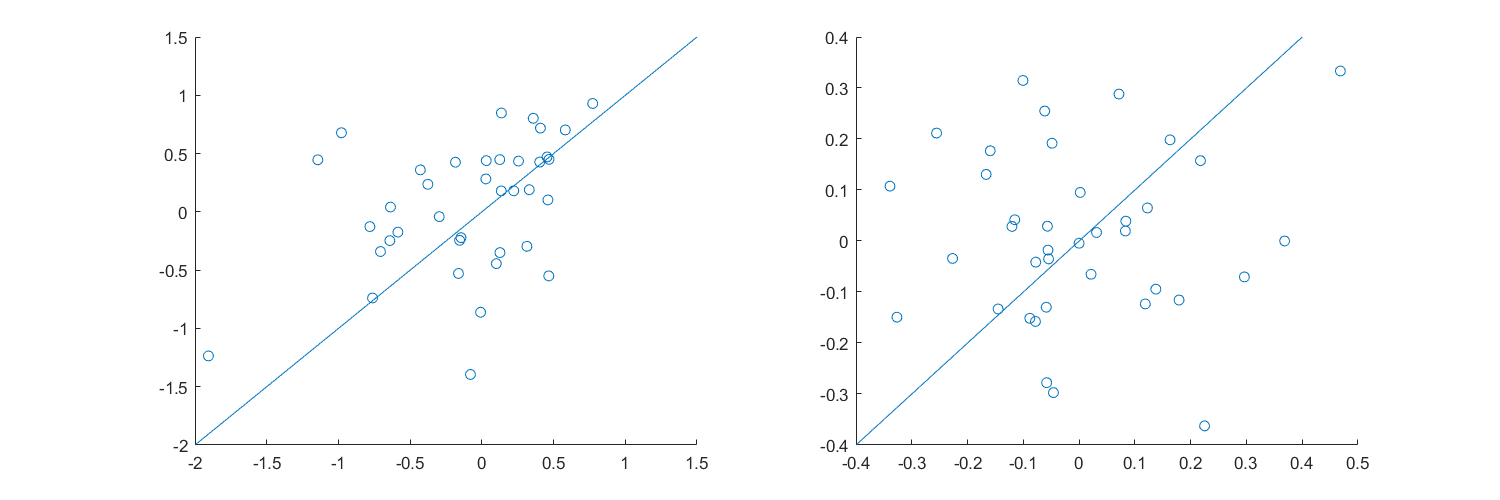

% ambig attitude, constrained, gain
figure('Position', [0,0,1200,400])

subplot(1,2,1)
scatter(day1.beta_3, day2.beta_3)
x = linspace(-2,1.5);
y = x;
line(x,y)

subplot(1,2,2)
scatter(day1.L_amb_risk50, day2.L_amb_risk50)
line(linspace(-0.4, 0.4), linspace(-0.4, 0.4))